# Simple Areal-tp-point exemple with actual data.

## Référance:

Kyriakidis, P. C., & Yoo, E. H. (2005). Geostatistical prediction and simulation of point values from areal data. *Geographical Analysis*, *37*(2), 124–151. https://doi.org/10.1111/j.1538-4632.2005.00633.x

addpath(genpath('./.'));  % Add folder and sub-folder to path
dbstop if error  % activate debug in error
clear all; close all
load('result-A2PK/GEN-Run_1_2017-05-07_14-37');

Define the synthetic case study

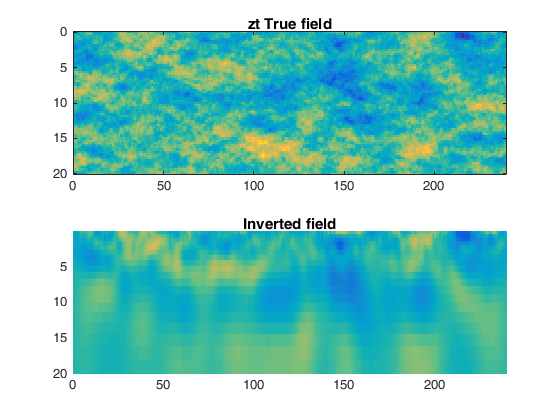

[kern.prior,kern.axis_prim] = ksdensity(sigma_true(:));
parm.nscore=1;
Nscore = nscore(kern, parm, 0);
NSigma.x=Sigma.x_raw; NSigma.y=Sigma.y_raw; 
[NSigma.X, NSigma.Y] = meshgrid(Sigma.x_raw, Sigma.y_raw);
d = reshape(Nscore.forward(Sigma.d_raw(:)) ,numel(NSigma.y),numel(NSigma.x));
zt = reshape(Nscore.forward(sigma_true(:)), grid_gen.ny, grid_gen.nx);
c_axis=[ min(zt(:)) max(zt(:)) ];
subplot(2,1,1);imagesc(grid_gen.x, grid_gen.y, zt); caxis(c_axis); title('zt True field');
subplot(2,1,2); surf(NSigma.x, NSigma.y, d,'EdgeColor','none'); caxis(c_axis); title('Inverted field'); view(2); axis tight; set(gca,'Ydir','reverse'); box on

Built the matrix G which link the true variable zt to the measured coarse scale d

G = zeros(numel(NSigma.X),grid_gen.nxy);
for ij=1:grid_gen.nxy
     [~,id_z]=min((grid_gen.X(ij)-NSigma.X(:)).^2 + (grid_gen.Y(ij)-NSigma.Y(:)).^2);
     G(id_z,ij)=1;%/(NSigma.dx*NSigma.dy);
end
% % Different version to use Sigma.rad
% for ij = 1:numel(NSigma.X)
%     G(ij,G(ij,:)==1) = Sigma.rad_raw(ij) ./ sum(G(ij,:)==1);
%     G(ij,G(ij,:)==0) = ( 1-Sigma.rad_raw(ij)) ./ sum(G(ij,:)==0);
% end
for ij = 1:numel(NSigma.X)
    G(ij,G(ij,:)==1) = 1 ./ sum(G(ij,:)==1);
end


Compare actual ERT inverted and corresponding averaged Electricit

dG = reshape(G * zt(:), numel(NSigma.y), numel(NSigma.x));
Gt = d(:) * zt(:)' / (zt(:) * zt(:)');

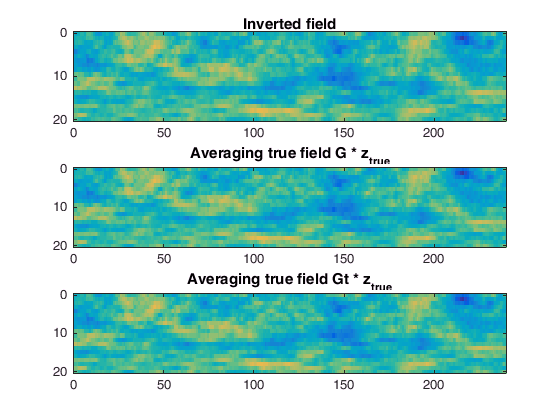

dGt = reshape(Gt * zt(:), numel(NSigma.y), numel(NSigma.x));

subplot(3,1,1); surf(NSigma.x, NSigma.y, d); caxis(c_axis); title('Inverted field'); view(2); axis tight; set(gca,'Ydir','reverse'); box on
subplot(3,1,2); surf(NSigma.x, NSigma.y, dG); caxis(c_axis); title('Averaging of the true field G * z_{true}'); view(2); axis tight; set(gca,'Ydir','reverse'); box on
subplot(3,1,3); surf(NSigma.x, NSigma.y, dGt); caxis(c_axis); title('Using the true field to find Gt, Gt * z_{true}'); view(2); axis tight; set(gca,'Ydir','reverse'); box on

kriging prediction

Cz = covardm_perso([grid_gen.X(:) grid_gen.Y(:)], [grid_gen.X(:) grid_gen.Y(:)], gen.covar);
Czd = Cz * G';
Cd = G * Czd;
W=zeros(grid_gen.nxy,numel(NSigma.X));
for ij=1:grid_gen.nxy
    W(ij,:) = Cd \ Czd(ij,:)';
end
zh = reshape( W * d(:), grid_gen.ny,grid_gen.nx);
imagesc(grid_gen.x, grid_gen.y, zh); caxis(c_axis); title('zh Kriging prediction based on d');

Build unconditional realization

zs = fftma_perso(gen.covar, grid_gen);
imagesc(grid_gen.x, grid_gen.y, zs); caxis(c_axis); title('zs Unconditional Realization');
ds = reshape(G * zs(:), numel(NSigma.y), numel(NSigma.x));
imagesc(grid_gen.x, grid_gen.y, ds); caxis(c_axis); title('ds Average of Unconditional Realization');
zhs = reshape( W * ds(:), grid_gen.ny,grid_gen.nx);
imagesc(grid_gen.x, grid_gen.y, zhs); caxis(c_axis); title('zhs Kriging prediction based on ds');

Build condtional realization

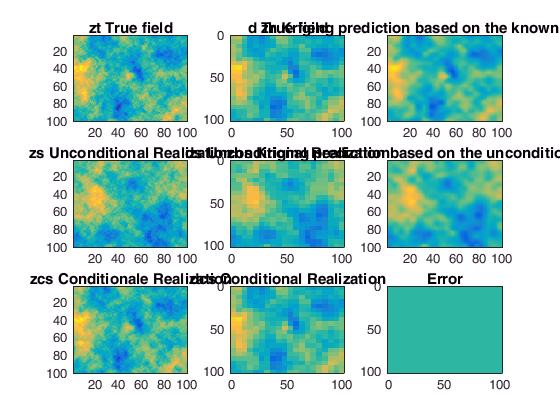

zcs = zh + (zs - zhs);
imagesc(grid_gen.x, grid_gen.y, zcs); caxis(c_axis); title('zcs Conditionale Realization');
dcs = reshape(G * zcs(:), numel(NSigma.y), numel(NSigma.x));
imagesc(grid_gen.x, grid_gen.y, dcs); caxis(c_axis); title('dcs Average of Conditional Realization');